# DSZOB, cvičenie 6.

## **Zadanie:**

## **Úloha 1 **Filtrácia signálu gaussovským filtrom v časovej i frekvenčnej doméne

**a)**

- definujte fitracne jadro ako gaussovsku funkciu o dĺžke n (napr. 32 alebo 64)

- použite konvolúciu (funkciu **conv**) na filtrovanie signálu týmto gaussovským filtračným jadrom

**b)**

- vypočítajte spektrum filtračného jadra

- týmto spektrom filtračného jadra vynásobte (po prvkoch) spektrum vstupného signálu

- výstup dajte na vstup spätnej transformácii

Porovnavjte tieto dva spôsoby filtrácie !

Ako vstupný signál použite ľubovoľný signál zvuku alebo syntetizovaný zvuk so šumom.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

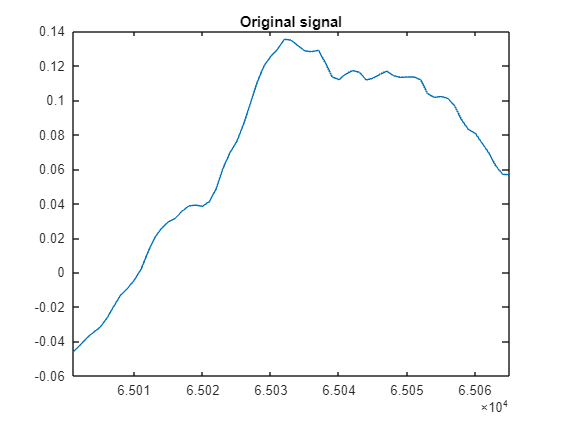

% Riesenie / Solution
    fado = importdata("Fado1.wav");
    fs = fado.fs;
    rawSignal = fado.data(:,1);
    rawSignal = rawSignal';
    figure
    plot(rawSignal)
    title("Original signal")
    xlim([65001 65065])

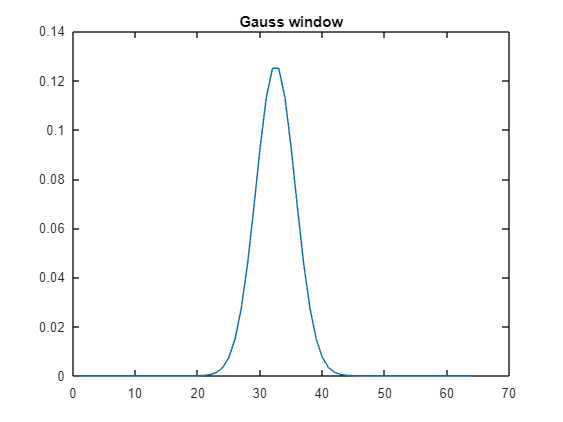


% 1.1.1 definovali sme fitracne jadro ako gaussovsku funkciu o dĺžke n (napr. 32 alebo 64)
        gausswWindow = gausswin(64, 10);
        gausswWindow = gausswWindow / sum(gausswWindow); %normalizácia gausovho okienka pre zachovanie amplitúd
        figure
        plot(gausswWindow)
        title("Gauss window")

1.1.1 V tejto sub-sekcií bolo vytvorené filtračné jadro, konkrétne gaussovo okienko pre úpravu pôvodného signálu. Spomenuté jadro bolo nastavené, pre určenú dĺžku 64 a šírku 10, vzhladom na to že táto šírka bola kompromisom. V poslednm rade toto jadro bolo normalizované ako prevencia pred skreslením amplitúdových hodnoť signálu po filtrácií.

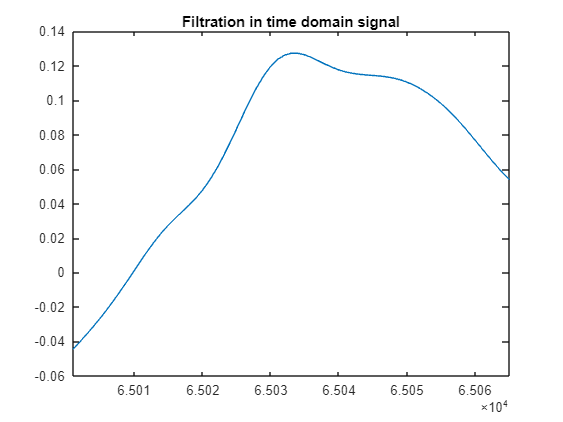

% 1.1.2 použili sme konvolúciu (funkciu conv) na filtrovanie signálu,
% (týmto gaussovským filtračným jadrom)
        timeDomainSignal = conv(rawSignal, gausswWindow, "same");
        figure
        plot(timeDomainSignal)
        title("Filtration in time domain signal")
        xlim([65001 65065])

1.1.2 V tejto sub-sekcí došlo k použitiu filtračného jadra na pôvodnom signále, výsledkom čoho je signá ktorého priebeh je omnoho "jemnejší" ako jeho pôvodný signál. Tu je potrebné ešte podotknuť že v conv, funkcií bol pridaní parameter "same" za účelom zachovania pôvodnej dlźky výsledného signálu.

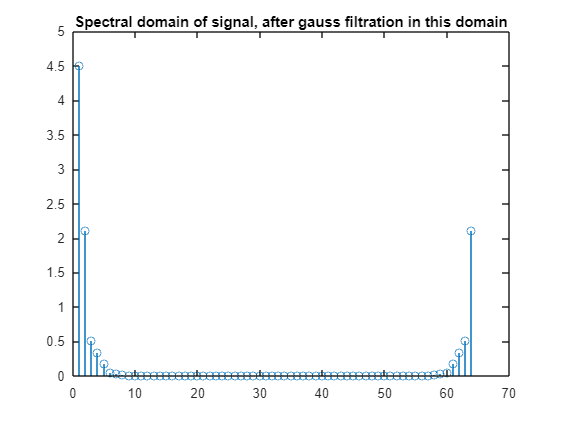


% 1.2.1 vypočítali sme spektrum filtračného jadra
        choosenSignal512 = rawSignal(65001:65064);
        nfftGauss = fft(gausswWindow');
        nfftSignal = fft(choosenSignal512);
% 1.2.2 týmto spektrom filtračného jadra sme vynásobily (po prvkoch) spektrum vstupného signálu
        nfftFiltSignal = nfftSignal.*abs(nfftGauss);  %nfftGauss.*abs(nfftGauss');
        figure
        stem(abs(nfftFiltSignal))
        title("Spectral domain of signal, after gauss filtration in this domain")

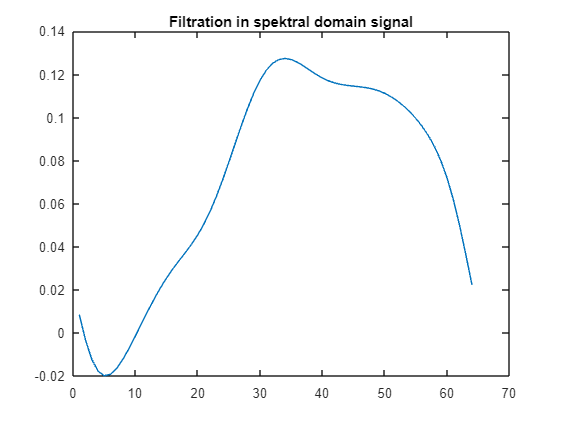

% 1.2.3 výstup (po transformácii) bol daný na vstup spätnej transformácii
        spectDomainSignal = ifft(nfftFiltSignal);
        figure
        plot(spectDomainSignal)
        title("Filtration in spektral domain signal")

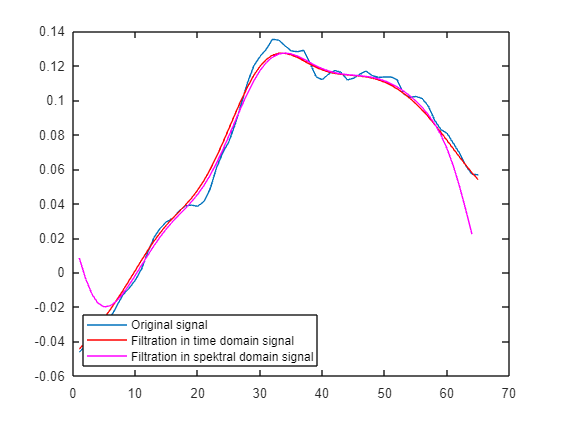



% Porovnali sme tieto dva spôsoby filtrácie, pomocou spojenia grafov týchto
% 3 signálov, originálneho, signálu filtrovaného v time domain a signálu
% filtrovaného v spectral domain. Výsledkom toho bola nájdena značná
% podobnosť grafov filtrovania, čo však bolo podmienené vstupnou šírkou
% filtračného jadra. Okrem toho grafy signálov po filtrovaní, mali
% "jemnejšií" priebeh ako originálny signál.
    figure
        plot(rawSignal(65001:65065))
    hold on 
        plot(timeDomainSignal(65001:65065), Color="red")
        plot(spectDomainSignal, Color="magenta")
        title("Composite graph, of original signal, and its 2 filtration (in different domains) results,")
        legend("Original signal","Filtration in time domain signal","Filtration in spektral domain signal", 'Location','southwest')
    hold off


    % Rozdiel v povodnom signále k tomu ktr. bol filtrovaný gaussovým
    % okienkom je v tom že jeho strmé maximá sú "zjemnené", reps. vývoj
    % krivky signálu ktr. bol v pôvodnom kostrbatý je po filtrovaní omnoho
    % hladší, bez strmím zmenám v hodnotách.
    % Rozdiel medzi filtraciou v časovej a spectrálnej je maly až na
    % okrajové vývoj, tie sa menia v prípade spectrálneho filtrovania, čím
    % viac je alfa hodnota gaussovho okna menšia (gaussove okno je užšie)


1.2 V tejto sekcí došlo k aplikácií filtračného jadra v spekrálnej doméne. Čoho výsledok sa značne líšíl (od filtrácie v časovej doméne) na zakladee šírky použitého jadra, Pri šírke 10 boli výsledné signály minimálne rozlišné (minimálne v rámci priebehu grafu)

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

a) LP filter

- Filtrujte signál v spektrálnej oblasti za pomoci LP filtra (celý signál cez okienka)

- Použite rôzne hraničné hodnoty frekvencie

- Vizualizujte spektrogramom. Frekvenčná osa má byť preškálovaná na frekvencie v Hz!

b) HP filter

- Filtrujte signál v spektrálnej oblasti za pomoci HP filtra (celý signál cez okienka)

- Použite rôzne hraničné hodnoty frekvencie (cut-off freqency)

- Vizualizujte spektrogramom. Frekvenčná osa má byť preškálovaná na frekvencie v Hz!

Ako vstupné dáta použite:

- zvukový signál ladičky

- zvukový signál hudby

- zvukový signál reči

Vyhodnoťte zmenu kvality vypočutého filtrovaného zvuku pre rôzne typy  vstupného signálu a rôzne filtre.

Nájdite hraničné  frekvencie pre LP a  HP, pri ktorej je reč na nahrávke ešte zrozumiteľná. 

Nezabudnite na to,  že pri filtrácií volíte hraničnú frekvenciu, nie hraničný spektrálny koeficient. Je teda nutné previesť indexy spektrálnych koeficientov na  frekvenciu.

### 2.1 LP filter

#### 2.1.1 Filtrujte signál v spektrálnej oblasti za pomoci LP filtra

% Riesenie / Solution
    %(celý signál cez okienka), ---------> zmen ho na frekvečný graf, (for cyklus)
    [LP_outSignal_T700, LP_sampleWindowOrig, LP_sampleWindowAfter, LP_freqVect1] = filtDCTSignal(rawSignal, 700, 512, fs, true);

- `Náhlad na okno signálu po redukcií LP:`

    figure
            tiledlayout(2,1)
                nexttile
                    stem(LP_freqVect1,LP_sampleWindowOrig)
                       title("LP: Hudba, Frequency graph of the signal widndow 512:")
                        xlabel("Hz");
                        ylabel("Amplitude");
                        xlim([-100 2500])
                 nexttile
                     stem(LP_freqVect1,LP_sampleWindowAfter)
                        title("LP: Hudba, Reduced-Frequency graph of the signal widndow 512")
                        xlabel("Hz");
                        ylabel("Amplitude");
                        xlim([-100 2500])

- `Nahlad na signál po redukcií cez LP:`

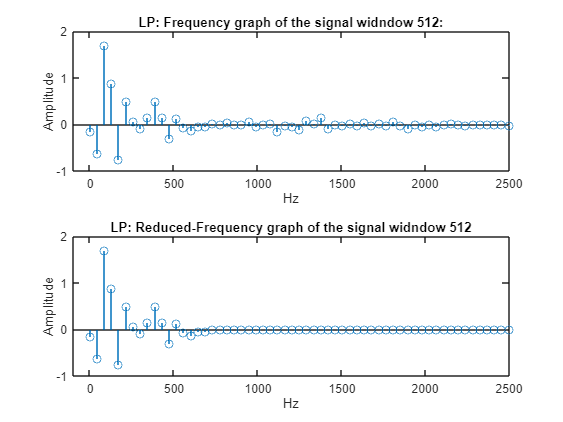

    figure

        tiledlayout(2,1)
            nexttile
                plot(rawSignal)
                title('LP: Hudba, pôvodný signál:')
            nexttile
                plot(LP_outSignal_T700)
                title('LP: Hudba, filtrovaný signál cez LP v spektralnej doméne:')

### 2.1.2 Použité rôzne hraničné hodnoty frekvencie a uskutočnenie Hudby po LP

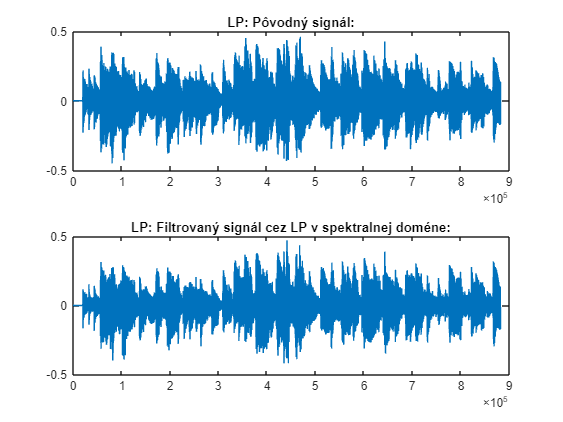

% Tuto časť som spojil s posledními taskami pre Hudbu, v rámci funkcie
% playRec bolo vytvorených niekolko redukovaných signálových rámcov, na

% základe zadaných tresholdov ktr. sú parametre 4. - 8. . Tieto signály
% boli spracované do nahrávok a boli spustené a analizované.
playRedRec(1, 3, rawSignal, 5000, 2000, 1000, 500, 200, fs, true)

#### 2.1.3 Vizualizujte spektrogramom. Frekvenčná os v Hz.

    % Tu je porovnanie pôvodného rámca signálu s rámcom po jeho LP redukcií s
    % tresholdom 700Hz, čo je vyditelné v grafe, kde okolo 700Hz a nad sú hodnoty
    % odstrihnuté
    figure
        tiledlayout(2,1)
            nexttile
                spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
                title('LP: Hudba, Spektogram pôvodného signálu:')
                set(gca,'YTickLabel', (0:2000/4:2000))
                ylabel('Frequency (Hz)')
                ylim([0 2])
            nexttile
                spectrogram(LP_outSignal_T700, hamming(512), 256, 512, fs, "yaxis")
                title('LP: Hudba, Spektogram filtrovaného signálu cez LP v spektralnej doméne:')
                set(gca,'YTickLabel', (0:2000/4:2000))
                ylabel('Frequency (Hz)')
                ylim([0 2])

### 2.2 filter

#### 2.2.1 Filtrujte signál v spektrálnej oblasti za pomoci HP filtra

    % Riesenie / Solution
    %(celý signál cez okienka), ---------> zmen ho na frekvečný graf, (for cyklus)
    [HP_outSignal_T700, HP_sampleWindowOrig, HP_sampleWindowAfter, HP_freqVect1] = filtDCTSignal(rawSignal, 700, 512, fs, false);

- `Náhlad na okno signálu po redukcií HP:`

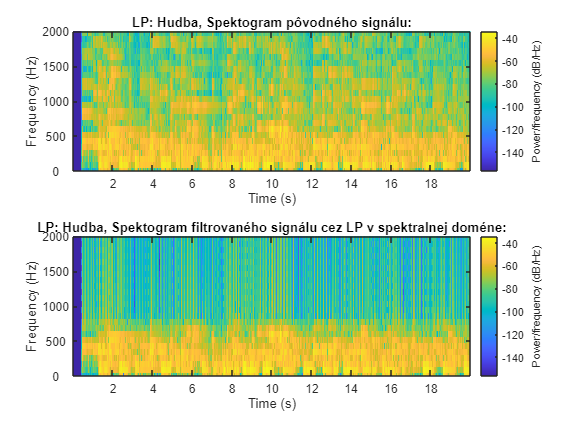

    figure
            tiledlayout(2,1)
                nexttile

                    stem(HP_freqVect1,HP_sampleWindowOrig)
                       title("HP: Hudba, Frequency graph of the signal widndow 512:")
                        xlabel("Hz");
                        ylabel("Amplitude");
                        xlim([-100 2500])
                 nexttile
                     stem(HP_freqVect1,HP_sampleWindowAfter)
                        title("HP: Hudba, Reduced-Frequency graph of the signal widndow 512")
                        xlabel("Hz");
                        ylabel("Amplitude");
                        xlim([-100 2500])

- `Nahlad na signál po redukcií cez HP:`

    figure
        tiledlayout(2,1)
            nexttile
                plot(rawSignal)
                title('HP: Hudba, Pôvodný signál:')
            nexttile
                plot(HP_outSignal_T700)
                title('HP: Hudba, Filtrovaný signál cez HP v spektralnej doméne:')

### 2.2.2 Použite rôzne hraničné hodnoty frekvencie  (cut-off freqency)  a uskutočnenie Hudby po HP

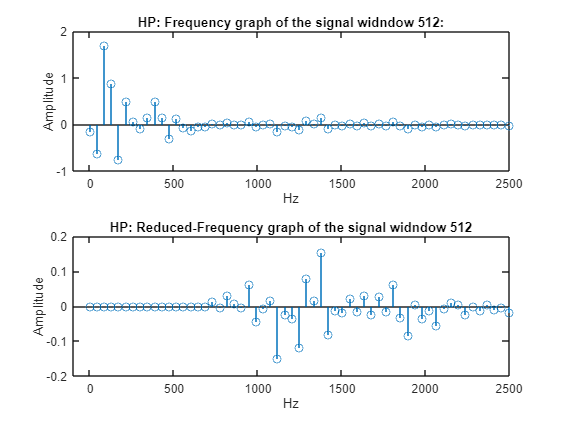

% Tuto časť som spojil s posledními taskami pre Hudbu, v rámci funkcie
% playRec bolo vytvorených niekolko redukovaných signálových rámcov, na
% základe zadaných tresholdov ktr. sú parametre 4. - 8. . Tieto signály

% boli spracované do nahrávok a boli spustené a analizované, čoho výsledok
% je na konci 2. tasku.
playRedRec(1, 3, rawSignal, 200, 500, 1000, 2000, 5000, fs, false)

### 2.2.3 Vizualizujte spektrogramom. Frekvenčná os v Hz.

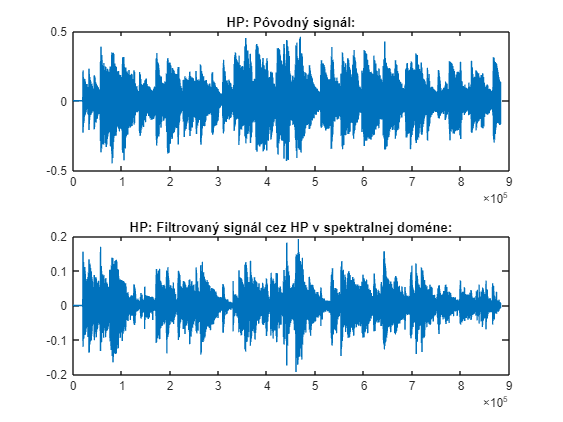

    % Tu je porovnanie pôvodného rámca signálu s rámcom po jeho HP redukcií s
    % tresholdom 700Hz, čo je vyditelné v grafe, kde okolo 700Hz a pod sú hodnoty
    % odstrihnuté
    figure
        tiledlayout(2,1)
            nexttile

                spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
                title('HP: Hudba, Spektogram pôvodného signálu:')
                set(gca,'YTickLabel', (0:2000/4:2000))
                ylabel('Frequency (Hz)')
                ylim([0 2])
            nexttile
                spectrogram(HP_outSignal_T700, hamming(512), 256, 512, fs, "yaxis")
                title('HP: Hudba, Spektogram filtrovaného signálu cez HP v spektralnej doméne:')
                set(gca,'YTickLabel', (0:2000/4:2000))
                ylabel('Frequency (Hz)')
                ylim([0 2])

### 2.3.1 Zvukový signál ladičky

  ladicka = importdata("ladicka.wav");
  fsLadicka = ladicka.fs;
  ladickaSignal = ladicka.data(:,1);
  ladickaSignal = ladickaSignal';
  figure
  plot(ladickaSignal)
  title("Ladicka, originalny signal")

  

playRedRec(1, 3, ladickaSignal, 10000, 2000, 1000, 500, 200, fsLadicka, true)

  playRedRec(1, 3, ladickaSignal, 200, 500, 1000, 2000, 10000, fsLadicka, false)

### 2.3.2 Zvukový signál reči

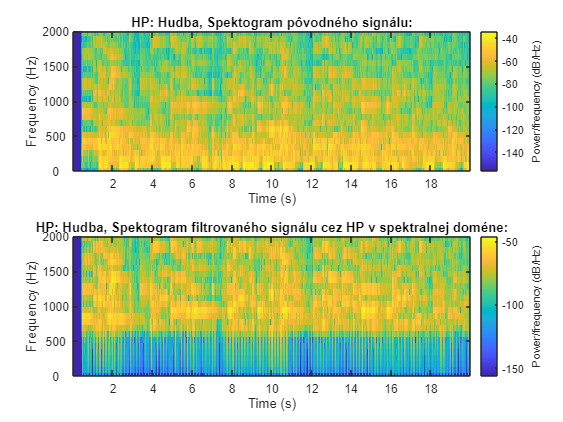

hlas = importdata("Hlas1.m4a");
 fsHlas = hlas.fs;

  hlasSignal = hlas.data();
  hlasSignal = hlasSignal';
  figure
  plot(hlasSignal)
  title("Reč, originalny signal") 

playRedRec(1, 3, hlasSignal, 5000, 2000, 1000, 500, 400, fsHlas, true)

playRedRec(1, 3, hlasSignal, 200, 500, 5000, 7500, 10000, fsHlas, false)

### 2.3.4

#### `Vyhodnoťte zmenu kvality vypočutého filtrovaného zvuku pre rôzne typy  vstupného signálu a rôzne filtre.`

- `Hudba, rozdiel LP a HP: pri LP sa bližením k cca. 200Hz tresholdu znehodnocuje signál jednak šumom a tlmením, naproti tomu HP ktorý nastavuje treshold od 200Hz vyššie sa postupne stráca, respektíve, utišuje sa (je počuť iba vyššie a vyššie tónové časti). Čo sa týka kvality počutéj nahrávky, lepší je HP, bez šumu(ktr. býva v nízkych frekvenciach).`

- `Ladicka, rozdiel LP a HP, rozdiel je menej badatelný u ladicky (kedže sa skladá z blizskych tónov), až v druhej polovici od 500Hz rozdiel je nápadný, u LP sa v tomto úseku znižuje/utlmuje počutelnosť nahrávky a zvyšuje sa hlasitosť šumu, u HP sa už od 500 objavuje značný šum i ked jeho pôsobnosť trvá iba do nahrávky tresholdu 1000Hz, kedže sa tóny nižších frekvencií strácajú stráca sa i šum, a ostávjú vrcholné frekvenčné tóny, podobne ako u nahravok hudby. Celková kvalita nahrávky bola v tomto prípade lepšia u LP nahrávok, až na tie posledné 2, pričom u HP bola jasná iba 1. a odtial kvalita značne padla (to je predpokladám z dôvodu toho že treshold prešiel hranicu zdrojovej frekvencie ladicky).`

- `Reč, rozdiel LP a HP, u LP opäť má priebeh zvišovania sa šumu až je počuť iba tempo a šum okolo tresholdu 200Hz-300Hz, a tlmenia zvuku (odstrihanie vysokých frekvencií), u HP sa na druhej nahrávke objavuje tiež šum, ale rýchlo mizne a z hlasu sa stáva šepot. Kde iba vrcholy reči sú zrozumitelné.`

#### `Nájdite hraničné  frekvencie pre LP a  HP, pri ktorej je reč na nahrávke ešte zrozumiteľná. `

- ` LP: treshold kde je posledne reč ešte zrozumitelná: 500Hz-400Hz`

- ` HP: treshold kde je posledne reč ešte zrozumitelná: 5000Hz~7500Hz sú tažkopádne rozoznatelné hovorené čísla 1,2,3,4,5,6`

## Funkcie

### 1. Funkcia zahratie nahravok, ktorých signál bol redukovaný 

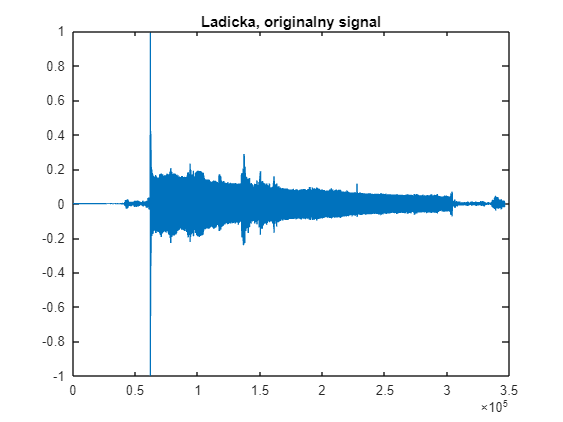

function playRedRec(playStart, playEnd, originalSignal, tresh1, tresh2, tresh3, tresh4, tresh5, fs, lowPass)
    [outSignal1,~,~,~] = filtDCTSignal(originalSignal, tresh1, 512, fs, lowPass);
        rec1 = audioplayer(outSignal1, fs);
            playblocking(rec1,  [playStart,playEnd*fs])
    

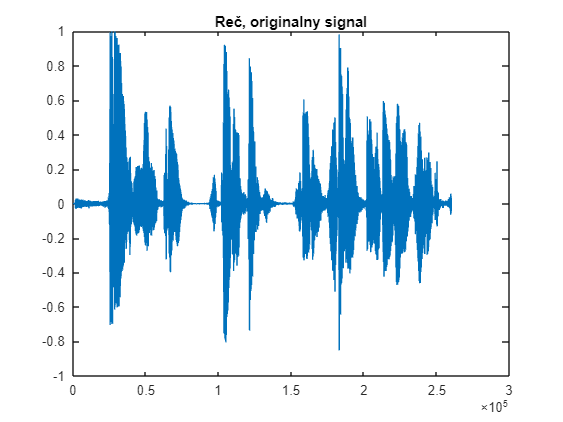

    [outSignal2,~,~,~] = filtDCTSignal(originalSignal, tresh2, 512, fs, lowPass);
        rec2 = audioplayer(outSignal2, fs);
            playblocking(rec2,  [playStart,playEnd*fs])
    
    [outSignal3,~,~,~] = filtDCTSignal(originalSignal, tresh3, 512, fs, lowPass);
        rec3 = audioplayer(outSignal3, fs);
            playblocking(rec3,  [playStart,playEnd*fs])
    
    [outSignal4,~,~,~] = filtDCTSignal(originalSignal, tresh4, 512, fs, lowPass);
        rec4 = audioplayer(outSignal4, fs);
            playblocking(rec4,  [playStart,playEnd*fs])
    
    [outSignal5,~,~,~] = filtDCTSignal(originalSignal, tresh5, 512, fs, lowPass);
        rec5 = audioplayer(outSignal5, fs);
            playblocking(rec5,  [playStart,playEnd*fs])

end

### 2. Funkcia redukcie signálu cez LP v spektralnej doméne, za pomoci DCT transformácie

function [signalOut, sampleBeforeOut, sampleAfterOt, freqVect] = filtDCTSignal(rawSignalPar, freqtTresholdPar, windowSize, fs, lowPass)
    M = round(length(rawSignalPar)/windowSize);
    if(M*windowSize > length(windowSize))
        M = M - 1;
    end
    signalOut = zeros(1,length(windowSize));
    halfFS = fs/2;
    % od 1 vzhladom na to že DCT nemá zápornu čast x osi, avšak toto je
    % kompenzované zápornými hodnotami v rámci y osi.
    freqVect = 1:halfFS/windowSize:halfFS;
    var = 1;
    for x = 1:(M)
        indexFrom = (x-1)*windowSize;
        indexTo = indexFrom+windowSize;
        windowX = rawSignalPar(1+indexFrom:indexTo);
        dctX = dct(windowX);
        % Zmen dctX na freq grahp
        if(lowPass)
            indx = (freqVect > freqtTresholdPar);
        else
            indx = (freqVect < freqtTresholdPar);
        end
        tempVect = dctX;
        dctX(indx) = 0;
        if(var == 1 && indexFrom > 65001)
            var = 0;
            sampleBeforeOut = tempVect;
            sampleAfterOt = dctX;
        end
        signalOut(1+indexFrom:indexTo) = idct(dctX);
    end
end




### 3. Funkcia redukcie signálu cez LP v spektralnej doméne, za pomoci FFT transformácie

function [signalOut,sampleBeforeOut,sampleAfterOt, freqVect] = filtFFTSignal(rawSignalPar, freqtTresholdPar, windowSize, fs, lowPass)
    M = round(length(rawSignalPar)/windowSize);
    if(M*windowSize > length(windowSize))
        M = M - 1;
    end
    signalOut = zeros(1,length(windowSize));
    halfFS = fs/2;
    freqVect = -halfFS + 1:fs/windowSize:halfFS;
    var = 1;
    for x = 1:(M)
        indexFrom = (x-1)*windowSize;
        indexTo = indexFrom+windowSize;
        windowX = rawSignalPar(1+indexFrom:indexTo);
        fftX = fft(windowX);
        % Zmen fftX na freq grahp
        if(lowPass)
            indx = (abs(freqVect) > freqtTresholdPar);
        else
            indx = (abs(freqVect) < freqtTresholdPar);
        end
        fftX = fftshift(fftX);
        tempVect = fftX;
        fftX(indx) = 0;
        if(var == 1 && indexFrom > 65001)
            var = 0;
            sampleBeforeOut = abs(tempVect);
            sampleAfterOt = abs(fftX);
        end
        fftX = ifftshift(fftX);
        signalOut(1+indexFrom:indexTo) = ifft(fftX);
    end
end
